**Reading the Dataset**

% Load the CSV file into a table
data = readtable('creditcard.csv')

data = 284807×31 table
    Time       V1          V2           V3          V4           V5           V6           V7           V8           V9          V10         V11         V12          V13          V14         V15          V16          V17          V18          V19          V20          V21           V22          V23          V24          V25          V26          V27           V28       Amount    Class
    ____    ________    


% Print the total number of rows and columns
fprintf('Total rows and columns\n\n');

Total rows and columns



fprintf('%d rows and %d columns\n', size(data, 1), size(data, 2));

284807 rows and 31 columns


fprintf('\n');


**Data Preprocessing**

% Calculate the sum of missing values for each column
missingSum = sum(ismissing(data));

% Display the sum of missing values for each column
disp(missingSum);

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0




% Display variable type information for each column
summary(data);

Variables:

    Time: 284807×1 double

        Values:

            Min                0
            Median         84692
            Max       1.7279e+05

    V1: 284807×1 double

        Values:

            Min        -56.408
            Median    0.018109
            Max         2.4549

    V2: 284807×1 double

        Values:

            Min        -72.716
            Median    0.065486
            Max         22.058

    V3: 284807×1 double

        Values:

            Min       -48.326 
            Median    0.17985 
            Max        9.3826 

    V4: 284807×1 double

        Values:

            Min         -5.6832
            Median    -0.019847
            Max          16.875

    V5: 284807×1 double

        Values:

            Min         -113.74
            Median    -0.054336
            Max          34.802

    V6: 284807×1 double

        Values


% Calculate statistical measures for each numeric variable
statisticalMeasures = array2table([mean(data{:, :}); std(data{:, :}); min(data{:, :}); ...
    prctile(data{:, :}, 25); median(data{:, :}); prctile(data{:, :}, 75); max(data{:, :})], ...
    'VariableNames', data.Properties.VariableNames, ...
    'RowNames', {'Mean', 'Standard Deviation', 'Minimum', '25th Percentile', 'Median', '75th Percentile', 'Maximum'});

% Display the rounded statistical measures
disp(round(statisticalMeasures, 2));

                             Time         V1        V2        V3       V4        V5         V6        V7        V8        V9       V10       V11      V12       V13      V14       V15      V16       V17      V18      V19      V20      V21       V22       V23       V24      V25      V26      V27       V28      Amount    Class
                          __________    ______    ______    ______    _


% Calculate statistical information for the "Not Fraud" class
notFraudPercentage = round(sum(data.Class == 0) / height(data) * 100, 2);
notFraudAmount = data.Amount(data.Class == 0);
notFraudStats = [mean(notFraudAmount), std(notFraudAmount), min(notFraudAmount), ...
    prctile(notFraudAmount, 25), median(notFraudAmount), prctile(notFraudAmount, 75), max(notFraudAmount)];

% Display the results for the "Not Fraud" class
fprintf('Not Fraud %%: %0.2f\n\n', notFraudPercentage);

Not Fraud %: 99.83



disp(notFraudStats);

   1.0e+04 *

    0.0088    0.0250         0    0.0006    0.0022    0.0077    2.5691



fprintf('\n');

% Calculate statistical information for the "Fraud" class
fraudPercentage = round(sum(data.Class == 1) / height(data) * 100, 2);
fraudAmount = data.Amount(data.Class == 1);
fraudStats = [mean(fraudAmount), std(fraudAmount), min(fraudAmount), ...
    prctile(fraudAmount, 25), median(fraudAmount), prctile(fraudAmount, 75), max(fraudAmount)];

% Display the results for the "Fraud" class
fprintf('Fraud %%: %0.2f\n\n', fraudPercentage);

Fraud %: 0.17



disp(fraudStats);

   1.0e+03 *

    0.1222    0.2567         0    0.0010    0.0092    0.1059    2.1259



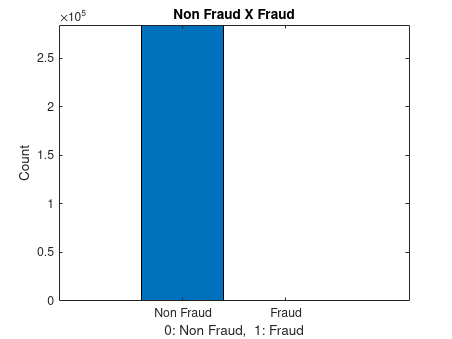


% Count the number of non-fraud and fraud transactions
classCounts = [sum(data.Class == 0), sum(data.Class == 1)];

% Calculate the percentage of non-fraud and fraud transactions
nonFraudPercentage = round(classCounts(1) / height(data) * 100, 2);
fraudPercentage = round(classCounts(2) / height(data) * 100, 2);

% Create a bar plot with custom colors
figure;
bar([0, 1], classCounts);
title('Non Fraud X Fraud');
ylabel('Count');
xlabel('0: Non Fraud,  1: Fraud');
xticks([0, 1]);
xticklabels({'Non Fraud', 'Fraud'});
ylim([0, max(classCounts) + 100]);
colormap([0.8 0.1 0.1; 0.2 0.8 0.2]);  % Set custom colors for bars


% Display the percentage of non-fraud and fraud transactions
fprintf('Non Fraud %%: %0.2f\n', nonFraudPercentage);

Non Fraud %: 99.83


fprintf('Fraud %%: %0.2f\n', fraudPercentage);

Fraud %: 0.17


Separation of input variables from target variable

% Extract column names for input variables
feature_names = data.Properties.VariableNames(2:30);
% Extract column name for target variable
target = data.Properties.VariableNames(31:end);

% Extract input variables
data_features = data(:, feature_names);

% Extract target variable (The Class column)
data_target = data(:, target);


**Separating the data into training and testing sets**

% Set the random seed for reproducibility
rng(123);

% Define the train-test split
split = cvpartition(height(data_features), 'HoldOut', 0.3);

% Split the data into training and test sets
trainIndices = training(split);
testIndices = test(split);

X_train = data_features(trainIndices, :);
X_test = data_features(testIndices, :);
y_train = data_target(trainIndices, :);
y_test = data_target(testIndices, :);

% Ensure X_test is of type table
if ~istable(X_test)
    X_test = array2table(X_test);
end

**Building and training the logistic regression model simultaneously**

% Prepend a column of ones to the training data table for the bias term
X_train_augmented = [ones(size(X_train, 1), 1), table2array(X_train)];

% Initialize the weights randomly
num_features = size(X_train_augmented, 2);
weights = rand(num_features, 1);

% Set the learning rate and number of iterations
learning_rate = 0.01;
num_iterations = 1000;

% Perform gradient descent
for iter = 1:num_iterations
    % Calculate the predicted probabilities using the current weights
    z = X_train_augmented * weights;
    predicted_probs = sigmoid(z);
    
    % Calculate the error between the predicted probabilities and the true labels
    error = predicted_probs - table2array(y_train);
    
    % Update the weights using gradient descent
    gradient = X_train_augmented' * error;
    weights = weights - learning_rate * gradient;
end

% Store the trained model in a structure
model.weights = weights;
model.threshold = 0.5;
model.predict = @(X) double(sigmoid([ones(size(X, 1), 1), table2array(X)] * model.weights) >= model.threshold);


**Confusion Matrix - Model performance measures**

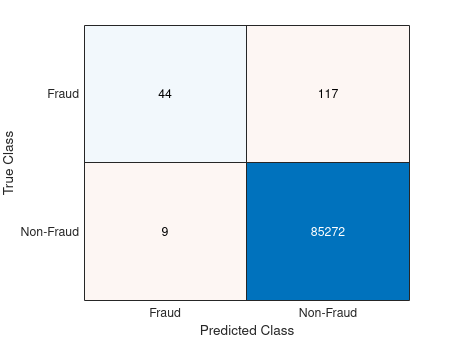

% Convert the test data table to a numeric matrix
X_test_numeric = table2array(X_test);

% Calculate predictions
y_pred = model.predict(X_test);

% Calculate confusion matrix
cmat = confusionmat(table2array(y_test), y_pred);

% Display confusion matrix
confusionchart(cmat, {'Non-Fraud', 'Fraud'});


% Calculate performance measures
accuracy = sum(diag(cmat)) / sum(cmat(:));
precision = cmat(1, 1) / sum(cmat(:, 1));
recall = cmat(1, 1) / sum(cmat(1, :));
f1_score = 2 * (precision * recall) / (precision + recall);

% Display performance measures
fprintf('Accuracy: %.16f\n', accuracy);

Accuracy: 0.9985253154186465


fprintf('Precision: %.16f\n', precision);

Precision: 0.9986298000913466


fprintf('Recall: %.16f\n', recall);

Recall: 0.9998944665283006


fprintf('F1 Score: %.16f\n', f1_score);

F1 Score: 0.9992617331692740


**Applying the undersampling technique and then splitting the data into training and testing datasets**

% The function "sum" counts the number of classes = 1 and saves it as an object "fraud_records"
fraud_records = sum(data.Class == 1);

% Defines the index for fraud and non-fraud in the lines:
fraud_indices = find(data.Class == 1);
not_fraud_indices = find(data.Class == 0);

% Randomly collect equal samples of each type:
under_sample_indices = randsample(not_fraud_indices, fraud_records, false);
data_undersampled = data([fraud_indices; under_sample_indices], :);
X_undersampled = data_undersampled(:, 2:30);
Y_undersampled = data_undersampled.Class;

% Split the undersampled data into training and testing sets
[X_undersampled_train, X_undersampled_test, Y_undersampled_train, Y_undersampled_test] = splitdata( ...
    X_undersampled, Y_undersampled, 0.3);

**Building and training the undersampled model simultaneously**

% Prepend a column of ones to the training data table for the bias term
X_undersampled_train_augmented = [ones(size(X_undersampled_train, 1), 1), table2array(X_undersampled_train)];

% Initialize the weights randomly
num_features = size(X_undersampled_train_augmented, 2);
weights_undersampled = rand(num_features, 1);

% Set the learning rate and number of iterations
learning_rate = 0.01;
num_iterations = 1000;

% Perform gradient descent on the undersampled data
for iter = 1:num_iterations
    % Calculate the predicted probabilities using the current weights
    z = X_undersampled_train_augmented * weights_undersampled;
    predicted_probs = sigmoid(z);
    
    % Calculate the error between the predicted probabilities and the true labels
    error = predicted_probs - Y_undersampled_train;
    
    % Update the weights using gradient descent
    gradient = X_undersampled_train_augmented' * error;
    weights_undersampled = weights_undersampled - learning_rate * gradient;
end

% Store the trained model in a structure
model_undersampled.weights = weights_undersampled;
model_undersampled.threshold = 0.5;
model_undersampled.predict = @(X) double(sigmoid([ones(size(X, 1), 1), table2array(X)] * model_undersampled.weights) >= model_undersampled.threshold);


**Confusion Matrix - Undersampled Model performance measures**

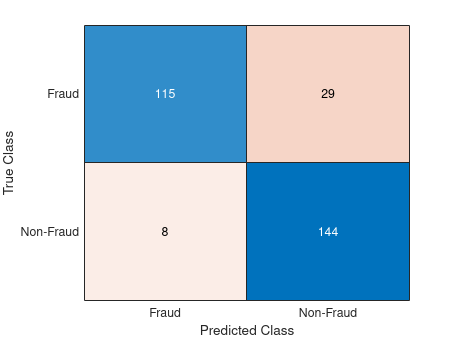

% Convert the test data table to a numeric matrix
X_undersampled_test_numeric = table2array(X_undersampled_test);

% Calculate predictions on the undersampled test data
y_undersampled_pred = model_undersampled.predict(X_undersampled_test);

% Calculate the confusion matrix for the undersampled predictions
cmat_undersampled = confusionmat(Y_undersampled_test, y_undersampled_pred);

% Display the undersampled confusion matrix
confusionchart(cmat_undersampled, {'Non-Fraud', 'Fraud'});


% Calculate performance measures on the undersampled data
accuracy_undersampled = sum(diag(cmat_undersampled)) / sum(cmat_undersampled(:));
precision_undersampled = cmat_undersampled(1, 1) / sum(cmat_undersampled(:, 1));
recall_undersampled = cmat_undersampled(1, 1) / sum(cmat_undersampled(1, :));
f1_score_undersampled = 2 * (precision_undersampled * recall_undersampled) / (precision_undersampled + recall_undersampled);

% Display performance measures on the undersampled data
fprintf('Undersampled Data Performance:\n');

Undersampled Data Performance:


fprintf('Accuracy: %.2f\n', accuracy_undersampled);

Accuracy: 0.88


fprintf('Precision: %.2f\n', precision_undersampled);

Precision: 0.83


fprintf('Recall: %.2f\n', recall_undersampled);

Recall: 0.95


fprintf('F1 Score: %.2f\n', f1_score_undersampled);

F1 Score: 0.89


**Confusion Matrix - Undersampled Model tested on original dataset performance measures**

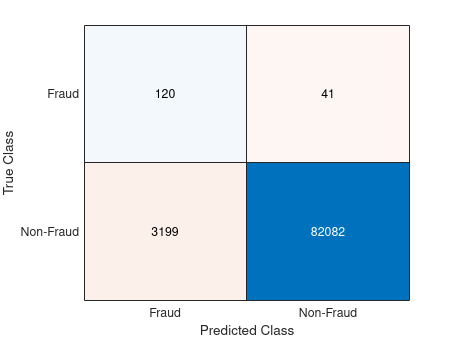

% Calculate predictions on the original test data using the undersampled model
y_pred_undersampled = model_undersampled.predict(X_test);

% Calculate the confusion matrix
cmat_undersampled = confusionmat(table2array(y_test), y_pred_undersampled);

% Display the confusion matrix
confusionchart(cmat_undersampled, {'Non-Fraud', 'Fraud'});


% Calculate performance measures
accuracy_undersampled = sum(diag(cmat_undersampled)) / sum(cmat_undersampled(:));
precision_undersampled = cmat_undersampled(1, 1) / sum(cmat_undersampled(:, 1));
recall_undersampled = cmat_undersampled(1, 1) / sum(cmat_undersampled(1, :));
f1_score_undersampled = 2 * (precision_undersampled * recall_undersampled) / (precision_undersampled + recall_undersampled);

% Display performance measures
fprintf('Undersampled Model on Original Dataset Performance:\n');

Undersampled Model on Original Dataset Performance:


fprintf('Accuracy: %.2f\n', accuracy_undersampled);

Accuracy: 0.96


fprintf('Precision: %.2f\n', precision_undersampled);

Precision: 1.00


fprintf('Recall: %.2f\n', recall_undersampled);

Recall: 0.96


fprintf('F1 Score: %.2f\n', f1_score_undersampled);

F1 Score: 0.98


**Measurement of classifier performance through the  AUC curve**

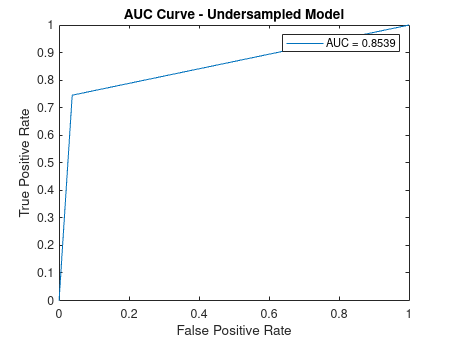

% Calculate predicted probabilities on the original test data using the undersampled model
y_pred_probs_undersampled = model_undersampled.predict(X_test);

% Calculate false positive rate (FPR) and true positive rate (TPR) for different thresholds
[fpr_undersampled, tpr_undersampled, ~, auc_undersampled] = perfcurve(table2array(y_test), y_pred_probs_undersampled, 1);

% Plot the AUC curve
figure;
plot(fpr_undersampled, tpr_undersampled);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('AUC Curve - Undersampled Model');
legend(['AUC = ' num2str(auc_undersampled, '%.4f')]);

Define the splitdata function:

function [X_train, X_test, y_train, y_test] = splitdata(X, y, test_ratio)
    indices = randperm(size(X, 1));
    split_point = floor((1 - test_ratio) * size(X, 1));
    
    X_train = X(indices(1:split_point), :);
    X_test = X(indices(split_point+1:end), :);
    y_train = y(indices(1:split_point), :);
    y_test = y(indices(split_point+1:end), :);
end

Define the sigmoid function:

function output = sigmoid(x)
    output = 1 ./ (1 + exp(-x));
end